clear;

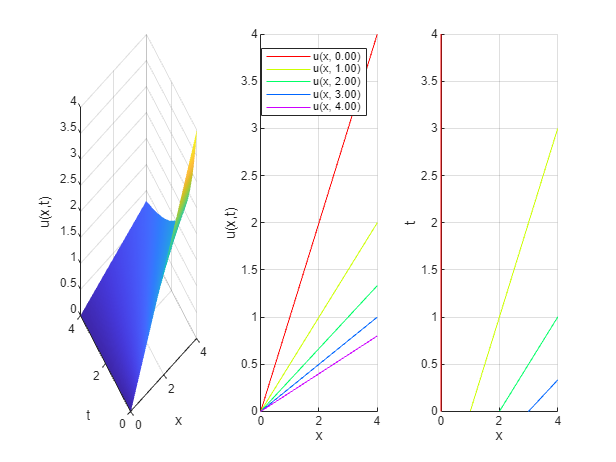

% u_t + u u_x = 0
% u(x,0) = x
% soln -> x/(t+1), for t>=0

u = @(x, t) x ./ (t+1);

N = 100;
xx = linspace(0, 4, N);
tt = linspace(0, 4, N);

PlotPDE(u, xx, tt, 5);

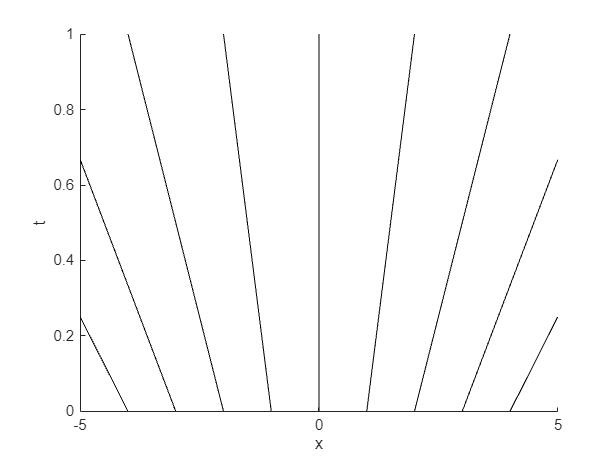

xMin = -5; xMax = 5;
N = 100; n = 11;
xx = linspace(xMin, xMax, N);
x0 = linspace(xMin, xMax, n);

u = @(x, t) x ./ (t+1);

f = figure();
view(2);
xlabel('x'); ylabel('t');
yticks(0:0.2:1);
axis([xMin xMax 0 1]);

hold on;
for i = 1:n
    m = double(u(x0(i),0));
    plot(xx, (xx-x0(i))/(m+eps), 'k');
end
hold off;
exportgraphics(f, [pwd, '/Figures/intro_f1.png']);

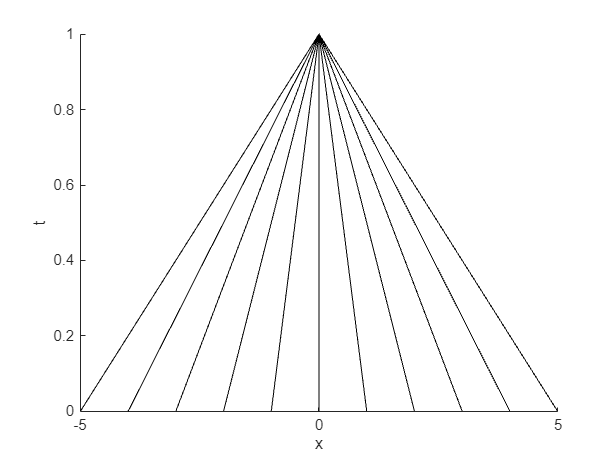

v = @(x, t) x ./ (t-1);

g = figure();
view(2);
xlabel('x'); ylabel('t');
yticks(0:0.2:1);
axis([xMin xMax 0 1]);

hold on;
for i = 1:n
    % m = double(v(x0(i),0));
    plot(xx, 1-xx/(x0(i)+eps), 'k');
end
hold off;
exportgraphics(g, [pwd, '/Figures/intro_f2.png']);

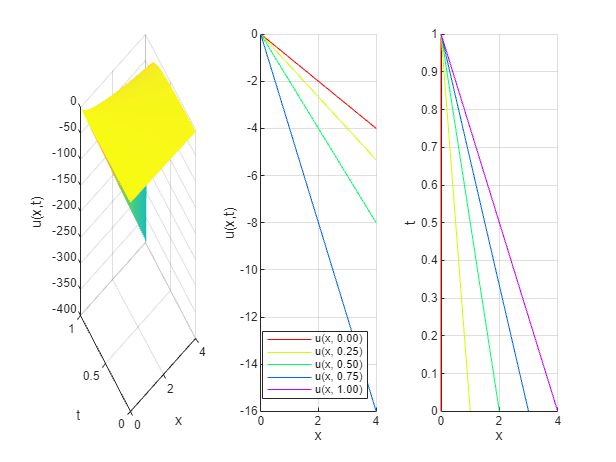

% u_t + u u_x = 0
% u(x,0) = x
% soln -> x/(t-1), for 0 <= t <1

u = @(x, t) x ./ (t-1);

N = 100;
xx = linspace(0, 4, N);
tt = linspace(0, 1, N);

PlotPDE(u, xx, tt, 5);

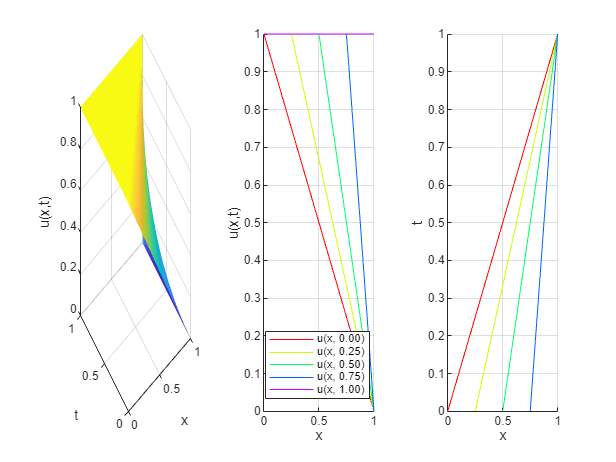

% u_t + u u_x = 0

syms u(x,t)
u(x,t) = piecewise(x <= t, 1, ...
                   (t<x)&(x<1), (1-x)/(1-t), ...
                   x >= 1, 0);

N = 100;
xx = linspace(0, 1, N);
tt = linspace(0, 1, N);

PlotPDE(u, xx, tt, 5);